mian = [0.01 0.5 3 -10 10];
r  = roots(mian)

r =  -42.3443 + 0.0000i
 -10.2412 + 0.0000i
   1.2928 + 0.7966i
   1.2928 - 0.7966i


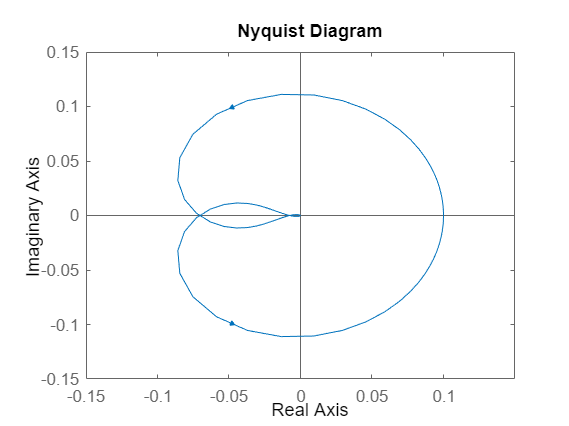

clear all, close all
licz = [1 1];
mian = [0.01 0.5 3 -10 10];
H = tf([licz], [mian]);
nyquist(H)
xlim([-0.15 0.15])

S  = allmargin(H)

S = struct with fields:
     GainMargin: [14.1376 130.8630]
    GMFrequency: [2.8766 15.5475]
    PhaseMargin: [1×0 double]
    PMFrequency: [1×0 double]
    DelayMargin: [1×0 double]
    DMFrequency: [1×0 double]
         Stable: 0


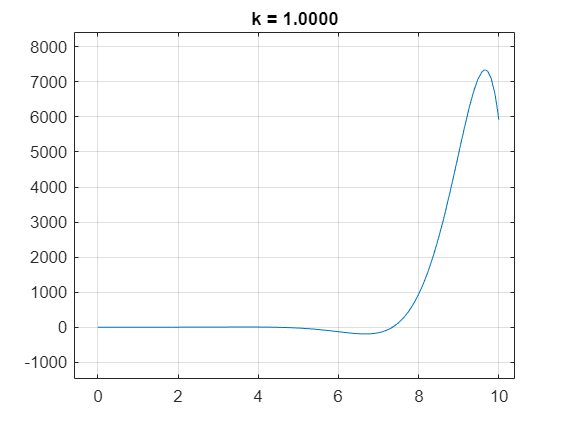

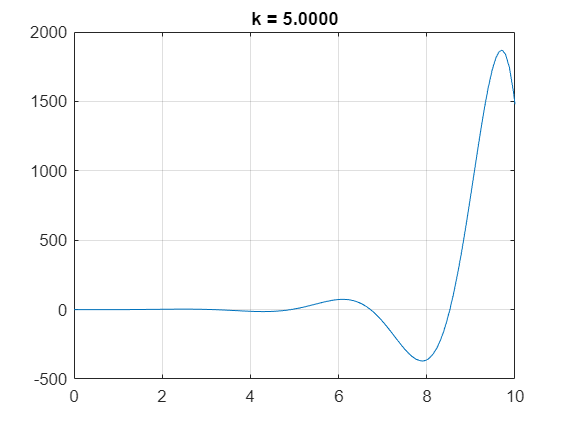

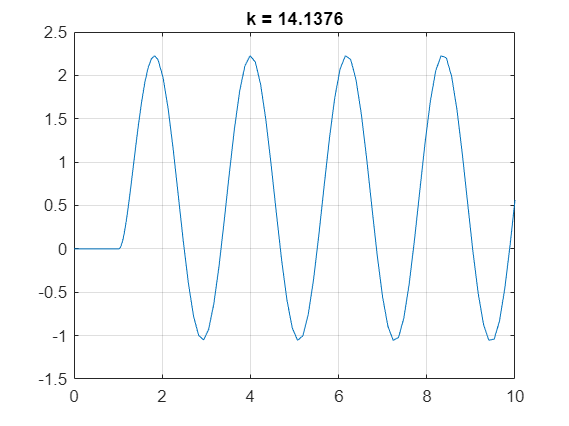

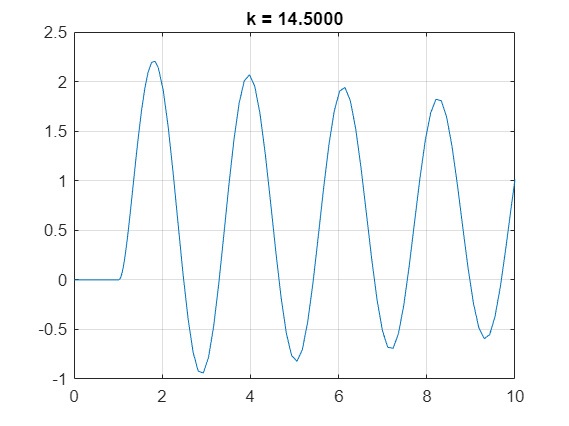

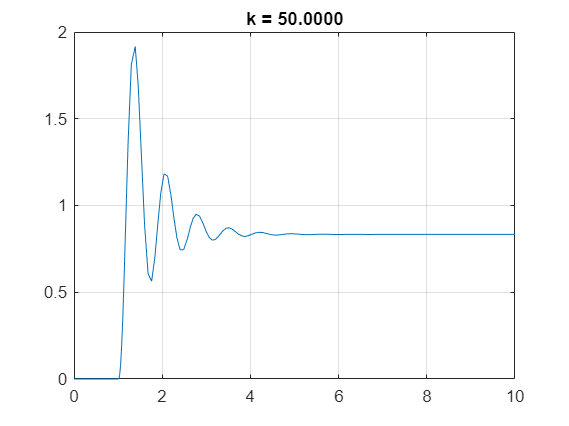

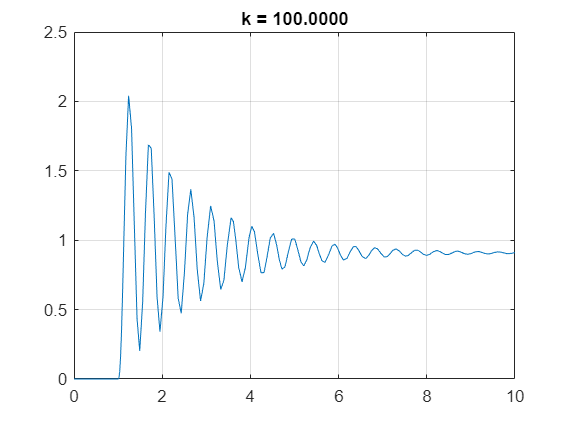

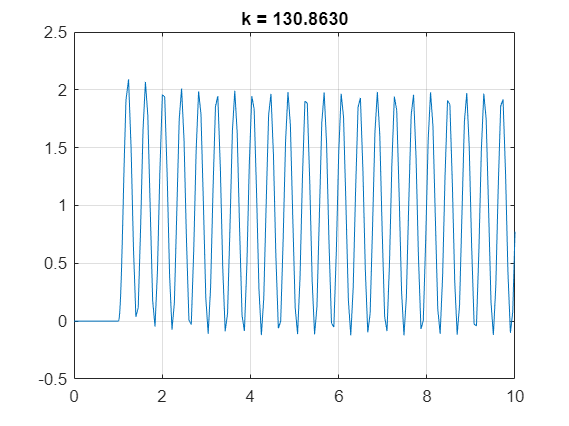

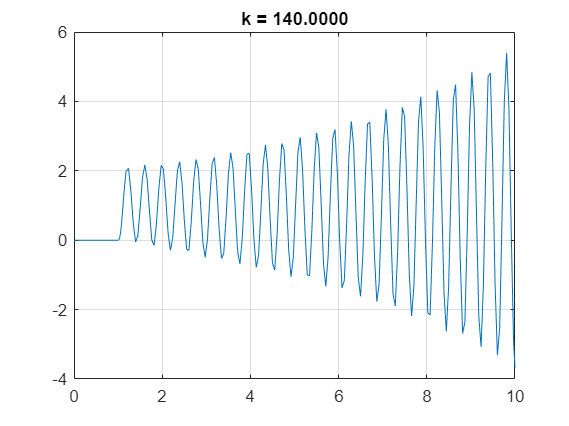

clear all, close all
K_tab = [1, 5, 14.1376, 14.5, 50, 100, 130.8630, 140, 150];
licz = [1 1];
mian = [0.01 0.5 3 -10 10];
for K = K_tab
    figure;
    sim("lab2_simulink");
    plot(ans.ScopeData.time, ans.ScopeData.signals.values);
    grid on;
    title(sprintf("k = %.4f", K));
end

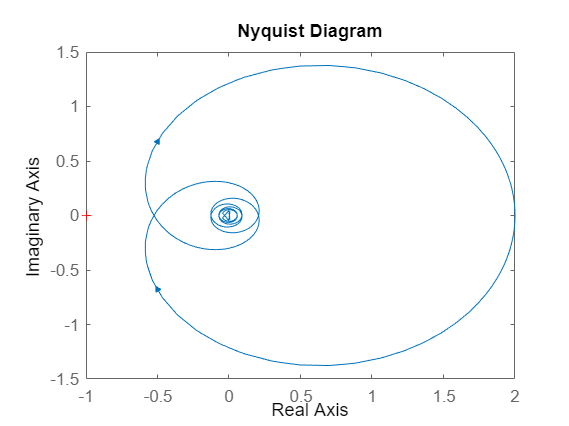

k=2;
mian = [1 1];
G = tf(k, mian, 'InputDelay', 0.5);
nyquist(G);